## **Курсовой проект**

## **По дисциплине: Моделирование и управление движением Роботов**

## **Тема:**

## **Планирование траекторий и управление движением робота-манипулятора при сварке изделий на производстве**

## **Авторы:**

**Соболев А.**

**Ису:**

**Коротков А.А.**

**Ису: **369910

Был произведен анализ роботов манипуляторв, представленных на рынке. Был произведен выбор робота манипулятора по ряду сравнительных харрактеристик:

Робот манипулятор Motoman HP6 имеет ряд преимуществ для сварки, среди которых:

1. Высокая точность и повторяемость: Благодаря своей точности и повторяемости, Motoman HP6 может обеспечить точность перемещения торчка сварочной головки и отличную сварочную точность, что в свою очередь дает более высококачественное сварочное соединение.

2. Быстрое время цикла: Благодаря быстрому времени цикла, в сочетании с высокой точностью, робот-сварщик Motoman HP6 может производить сварочные операции очень эффективно, что в свою очередь повышает производительность производства.

3. Гибкий парк кинематики: Motoman HP6 оснащен гибким парком кинематики, что позволяет роботу легко перемещаться и настраиваться в зависимости от требуемой задачи сварки. Это обеспечивает гибкость в производственном процессе и, следовательно, позволяет использовать робот-сварщик в различных областях промышленности.

4. Большая грузоподъемность: Motoman HP6 имеет большую грузоподъемность, что позволяет роботу манипулировать сварочными материалами и другими инструментами и оборудованием большого размера и веса

5. Надежность и долговечность: Робот-сварщик Motoman HP6, оснащенный высококачественными компонентами и инновационным программным обеспечением, обеспечивает высокую надежность и долговечность в работе. Он требует минимального обслуживания и ремонта, что позволяет снизить общую стоимость владения и эксплуатации робота манипулятора для сварки.

% Позиции старта и конца
qp_start = [0 0 0 0 0 0];
qp_end = [45 -82.5 67.5 113 -45 30];
qp_dest = deg2rad(qp_end)

qp_dest =     0.7854   -1.4399    1.1781    1.9722   -0.7854    0.5236


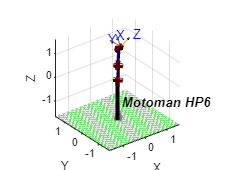

% Объявление переменных и констант
J_link = zeros(3,3);
rad = 0.05;

% Создание модели робота
mdl_puma560
mdl_motomanHP6
R=hp6;
R.plot(qp_dest)

% R.teach();
% Массы звеньев
R.links(1, 1).m = 10;
R.links(1, 2).m = 8;
R.links(1, 3).m = 8;
R.links(1, 4).m = 5;
R.links(1, 5).m = 4;
R.links(1, 6).m = 2

 
R = 
 
Motoman HP6:: 6 axis, RRRRRR, stdDH, slowRNE                     
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|       0.15|    -1.5708|          0|
|  2|         q2|          0|       0.57|   -3.14159|          0|
|  3|         q3|          0|      0.155|    -1.5708|          0|
|  4|         q4|     -0.635|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|     -0.095|          0|    3.14159|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% Центры масс звеньев
R.links(1,1).r = [R.links(1,1).a/2, 0, 0];
R.links(1,2).r = [R.links(1,2).a/2, 0, 0];
R.links(1,3).r = [R.links(1,3).a/2, 0, 0];
R.links(1,4).r = [R.links(1,4).a/2, 0, 0];
R.links(1,5).r = [R.links(1,5).a/2, 0, 0];
R.links(1,6).r = [R.links(1,6).a/2, 0, 0];

% Моменты инерций для цилиндрических звеньев
for i = 1:1:3
    % Jxx
    J_link(1,1) = R.links(1,i).m * R.links(1,i).a^2 / 12;
    % Jyy
    J_link(2,2) = R.links(1,i).m * R.links(1,i).a^2 / 12;
    % Jzz
    J_link(3,3) = R.links(1,i).m * rad^2;

    R.links(1,i).I = J_link;
end

% R.links(1,1).I = [R.links(1,1).m * R.links(1,1).a^2 / 12 * zeros(3,3)];
% R.links(1,2).I = [R.links(1,2).m * R.links(1,2).a^2 / 12 * zeros(3,3)];
% R.teach(1,3).I = [R.links(1,3).m * R.links(1,3).a^2 / 12 * zeros(3,3)];


% Моменты инерций для шарообразных звеньев
for i = 4:1:6
    % Jxx
    J_link(1,1) = R.links(1,i).m * rad^2 * 2 /5;
    % Jyy
    J_link(2,2) = R.links(1,i).m * rad^2 * 2 /5;
    % Jzz
    J_link(3,3) = R.links(1,i).m * rad^2 * 2 /5 ;

    R.links(1,i).I = J_link;
end

for i = 1:1:6
    R.links(1,i).Jm = p560.links(1,i).Jm;
end

## Решение обратной задачи динамики

[qp, qp_d, qp_dd] = jtraj(qp_start, qp_dest, 100);
Qp = R.rne(qp, qp_d, qp_dd);
Qp0 = R.rne(qp, zeros(100, 6), zeros(100, 6)); %силы для удерживания манипулятора на весу без движения
Gp = R.gravload(qp) %Силы тяжести

Gp =          0 -208.3153   34.9727         0         0         0
    0.0000 -208.3172   34.9745    0.0000    0.0000         0
   -0.0000 -208.3300   34.9873    0.0000    0.0003   -0.0000
   -0.0000 -208.3639   35.0212    0.0000    0.0009         0
   -0.0000 -208.4286   35.0860    0.0000    0.0021         0
    0.0000 -208.5329   35.1905    0.0000    0.0041         0
    0.0000 -208.6850   35.3430    0.0000    0.0069         0
   -0.0000 -208.8920   35.5511    0.0000    0.0108    0.0000
    0.0000 -209.1603   35.8215    0.0000    0.0159         0
    0.0000 -209.4955   36.1605    0.0000    0.0223   -0.0000


Mp = R.inertia(qp) %Матрицы нагрузок (масс)

Mp = Mp(:,:,1) =

   24.5327    0.0000   -0.0000    0.0110   -0.0000    0.0020
    0.0000   21.5240   -7.4506   -0.0000   -0.1447   -0.0000
   -0.0000   -7.4506    5.4186    0.0000    0.1447    0.0000
    0.0110   -0.0000    0.0000    0.0110    0.0000    0.0020
   -0.0000   -0.1447    0.1447    0.0000    0.0241    0.0000
    0.0020   -0.0000    0.0000    0.0020    0.0000    0.0020


Mp(:,:,2) =

   24.5331   -0.0000    0.0000    0.0110    0.0000    0.0020
   -0.0000   21.5241   -7.4507   -0.0000   -0.1447    0.0000
    0.0000   -7.4507    5.4186    0.0000    0.1447   -0.0000
    0.0110   -0.0000    0.0000    0.0110    0.0000    0.0020
    0.0000   -0.1447    0.1447    0.0000    0.0241    0.0000
    0.0020    0.0000   -0.0000    0.0020    0.0000    0.0020


Mp(:,:,3) =

   24.5353   -0.0000    0.0000    0.0110    0.0000    0.0020
   -0.0000   21.5247   -7.4510   -0.0000   -0.1447    0.0000
    0.0000   -7.4510    5.4186    0.0000    0.1447   -0.0000
    0.0110   -0.0000    0.0000    0.0

Cp = R.coriolis(qp, qp_d)

Cp = Cp(:,:,1) =

     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Cp(:,:,2) =

    0.0489   -0.0148    0.0148   -0.0004    0.0014   -0.0000
    0.0148    0.0141   -0.0318   -0.0000   -0.0008    0.0000
   -0.0148    0.0177   -0.0001    0.0000    0.0002   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0004    0.0007   -0.0002    0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000


Cp(:,:,3) =

    0.1916   -0.0579    0.0580   -0.0015    0.0054   -0.0000
    0.0579    0.0554   -0.1246   -0.0000   -0.0030    0.0000
   -0.0580    0.0695   -0.0003    0.0000    0.0006   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0015    0.0027   -0.0009    0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.000

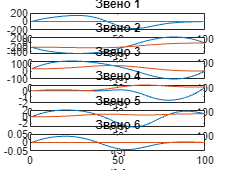

figure;
hold on;
grid on;
subplot (6,1,1)
plot(Qp(:,1))
hold on
plot(Qp0(:,1))
title("Звено 1")
xlabel('t [s]');
hold off;
subplot (6,1,2)
plot(Qp(:,2))
hold on
plot(Qp0(:,2))
title("Звено 2")
xlabel('t [s]');
hold off;
subplot (6,1,3)
plot(Qp(:,3))
hold on
plot(Qp0(:,3))
title("Звено 3")
xlabel('t [s]');
hold off;
subplot (6,1,4)
plot(Qp(:,4))
hold on
plot(Qp0(:,4))
title("Звено 4")
xlabel('t [s]');
hold off;
subplot (6,1,5)
plot(Qp(:,5))
hold on
plot(Qp0(:,5))
title("Звено 5")
xlabel('t[s]');
hold off;
subplot (6,1,6)
plot(Qp(:,6))
hold on
plot(Qp0(:,6))
title("Звено 6")
xlabel('t[s]');
hold off;

Звенья меняют свое положение относительно трех координат, поэтому данный график меняется.

Были введены параметры робота, вычислены инерциальные параметры. Так же была решена задача обратной динамики, были выведены матрицы масс  M, вектор кориолисовых и центробежных сил C и вектор гравитационных  сил G.